# Modeling and Optimizing a Battery Charging Profile

In this project, you will use MATLAB to model a battery charging profile. You will fit real lithium‑ion battery data in MATLAB, compute energy transfer through numerical integration, and analyze key performance characteristics such as charge‑rate behavior and efficiency losses.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Given data for a lithium-ion battery charging profile, use MATLAB to fit the equation for voltage provided in the Project Description.

- Plot the following curves: voltage vs. time, current vs. time, and power vs. time.

- Use integration to compute the total energy delivered to the battery (area under power-time curve).

- Analyze the rate of voltage change at different intervals (calculate derivatives), compute the time to reach 80% and 100% charge, and compute the energy lost due to resistance.

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Fit the voltage equation to a lithium-ion battery profile

Given real time-series voltage data for a lithium-ion battery, use MATLAB Curve Fitting Toolbox to fit the equation $V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\mathrm{RC}}} \right)$ and model the battery charging profile as a simple RC-circuit analog.

Load MathWorks example lithium-ion batteries data by following the steps [here](https://www.mathworks.com/help/predmaint/ug/data-analysis-and-feature-extraction-for-battery-raw-cycling-data.html). The page also includes information about the dataset, how the data was recorded, and the battery's maximum voltage.

**Note**: The battery from this example dataset has been cycled to failure (charged and discharged repeatedly). For this project, you may choose to use data from a single cycle and focus only on the period of time within a cycle that the battery is being charged. The battery is fully charged at 3.6V. This example battery uses a dynamic fast charging profile, but for this project, you will attempt to model the charging profile using a simple exponential capacitor charging equation.

Then, follow the workflow outlined in the [documentation](https://www.mathworks.com/help/curvefit/fit.html) to fit the voltage equation to your selected data. Plot the data and fitted curve in the same figure and, finally, print the goodness-of-fit statistics.

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% STEP 1
% Load the example battery dataset
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile)
load("singleCellLifeTimeData.mat")
head(data,5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    ___________


% STEP 2
% Pre-process the data to focus on a single cycle, and the period of time
% within that cycle that the battery was being charged
cycleData = data(data.Cycle_Index == 1, :)

cycleData = 1078×15 table
    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________   

cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1))

cycleData = 1078×15 table
    Data_Point    Test_Time    DateTime    Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    ___________

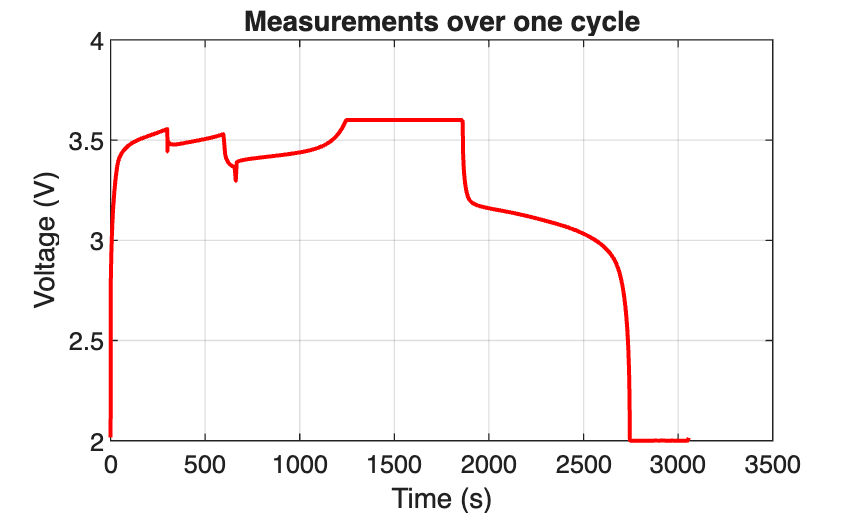

plot(cycleData.DateTime,cycleData.Voltage, '-r', 'LineWidth', 1.5)
ylabel('Voltage (V)')
xlabel("Time (s)")
title('Measurements over one cycle')
grid on %Add grid to the graph


% STEP 3
% Follow the provided workflow to fit the voltage equation to your selected
% data. 
% Hint: Vmax is known, so the only unknown in the equation is RC (also
% known as tau, the RC time constant - it is equivalent to the time it takes
% for a capacitor to reach ~63.2% of its max voltage). When you are fitting
% the curve to the data, you are essentially estimating the unknown
% parameter, tau.

targetVoltage = 0.632 * max(cycleData.Voltage);   % 2.2752 V

% Find the time at which voltage is closest to 2.2752 V
[~, idx] = min(abs(cycleData.Voltage - targetVoltage));
tau0 = cycleData.DateTime(idx);

battChargeEq = fittype( ...
    'Vmax*(1-exp(-t/tau))', ...
    'independent', 't', ...
    'dependent', 'v', ...
    'coefficients', {'tau'}, ...
    'problem', {'Vmax'});

Unrecognized function or variable 'fittype'.

fittype requires Curve Fitting Toolbox.


[battFit, gof] = fit( ... %Add gof to both return the fitted model and goodness-of-fit statistics.
    cycleData.DateTime, ...
    cycleData.Voltage, ...
    battChargeEq, ...
    'StartPoint', tau0, ...
    'Lower', eps, ...
    'problem', max(cycleData.Voltage));

% STEP 4
% Plot the data and the fitted curve in the same figure.

figure % Open a new figure graph, avoiding overwriting graph from step 2

% Plot fitted curve in blue and measured data in red.
plotLines = plot(battFit,'b--', ...
    cycleData.DateTime,cycleData.Voltage,'r-');
% Set both lines to the same width.
set(plotLines,'LineWidth',1.5);

% Label the graph.
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Cycle 1 Data and Fitted RC Curve')
legend('Cycle 1 voltage data','Fitted RC curve','Location','best')
grid on

% STEP 5
% Display the goodness-of-fit statistics.
fprintf('\nGoodness-of-Fit Statistics:\n')
fprintf('SSE: %.6f\n',gof.sse)                        % Total squared error
fprintf('R-squared: %.6f\n',gof.rsquare)             % Variation explained by the model
fprintf('Adjusted R-squared: %.6f\n',gof.adjrsquare) % R-squared adjusted for model size
fprintf('RMSE: %.6f V\n',gof.rmse)                   % Typical voltage fitting error
fprintf('Degrees of freedom: %d\n',gof.dfe)          % Data points minus fitted parameters

##  Task 2: Plot the electrical terms that express how energy moves in a circuit

To visualize the battery's charging policy, write code to visualize the current, voltage, and power measurements for one charging cycle. Present the visualization as one figure with three subplots, one each for:

- Voltage vs. time

- Current vs. time

- Power vs. time

Approach and methodology: 

From task 1, we started by using the data and the time that elapsed from 1 cycle of charge. While voltage and current used directly from the table, power had to be computed as P(t) = V(t) × I(t).  Voltage, current, and power were made into 3 subplots against time. Each subplot has its own axis labels and grid lines so the different variables could be compared directly.

Results and analysis:

The voltage level starts around 3.3 V and rises through its charging phase, plateauing near 3.5–3.6 V at around 1200–1850 s. This is consistent with a standard lithium-ion charging profile. The battery's current stays high early but tapers as it approaches its voltage limit, which is when the voltage steadies out. When step-like dips occurred in voltage, the current's dips also coincided exactly around 300–650 s. This represents the battery's resistance, where change in current results in an immediate voltage drop (V = I×R). Around 1850 s, the battery cycle transitions to a steady discharge where the current is about -4.5 A. The voltage decreases toward the 2.0 V cutoff at around 2750 s. The power subplot's shape is similar to current's subplot, which peaks near 22 W at the start and dips to about -14 W during discharge. The voltage stays stable compared to the other subplots with each phase. 

Challenges encountered:

There were some errors in the code like case sensitivity and that resulted in the response "unable to resolve the name" error that made me have to back track to fix. A variable I had a hard time with was "cycleData", which also caused problems when I used "cycleData.DateTime". It was a variable I had to reassign to make the section run without any errors. Another problem was running live script sections individually instead of running all the sections from top-to-bottom. Running all the sections caused variables from earlier sections to be undefined when a later section ran. Trying to compute power from the voltage and current datasets was also a challenge. Knowing to use  (`.*`) instead of (`*`) was something we had to figure out. 

Design decisions and trade-offs:

Since voltage, current, and power have different scales we used three subplots instead of one combined plot. If we used one combined plot for all those variables, it would be hard to read since they would be on the same axis. The tradeoff was 3 short graphs that were still hard to read. I had to add some extra code so that it could be read more easily. 

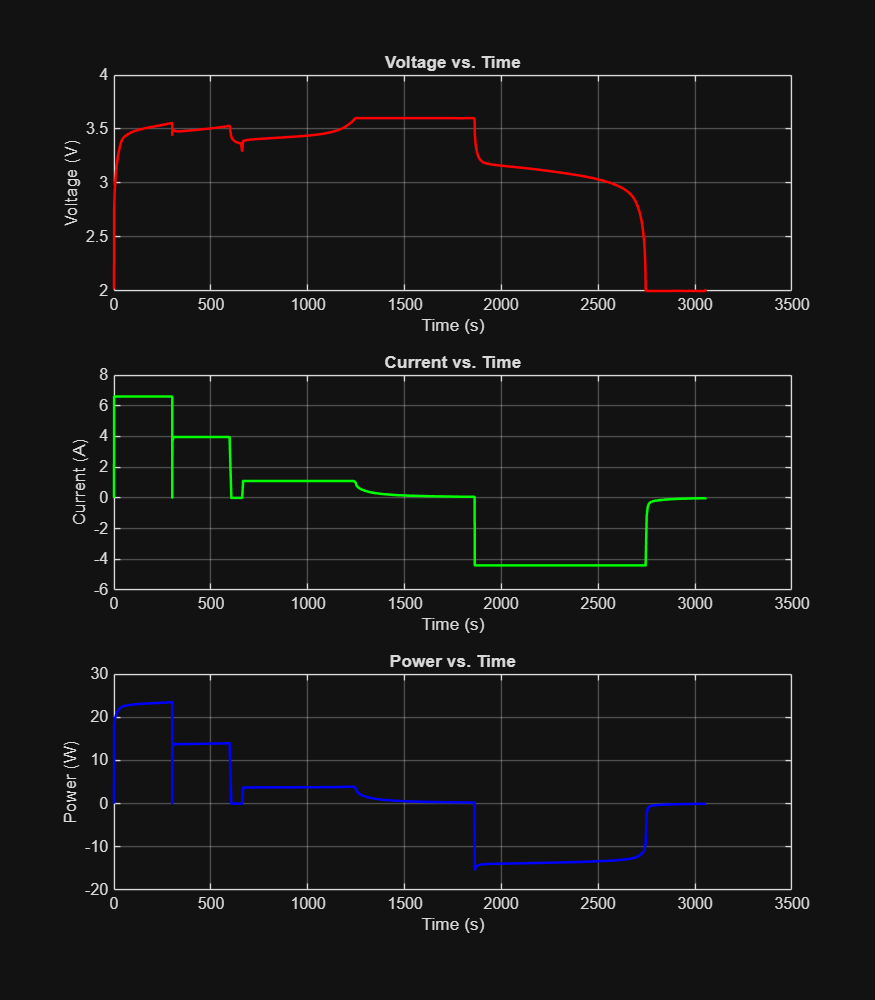

% Insert your code in the spaces below (or make use of helper functions and
% indicate where they can be found). Ensure your code is well-documented.

% STEP 1
% Create a figure handle and initialize the first subplot. Plot voltage vs.
% time.

S = load("singleCellLifeTimeData.mat");
cycleData = S.data(S.data.Cycle_Index == 1, :);
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));

figure('Position', [100, 100, 700, 800])
subplot(3, 1, 1); 
plot(cycleData.DateTime, cycleData.Voltage, '-r', 'LineWidth', 1.5)
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Voltage vs. Time');
grid on

% STEP 2
% Use a second subplot to plot current vs. time.

subplot(3, 1, 2); 
plot(cycleData.DateTime, cycleData.Current, 'g-', 'LineWidth', 1.5);  
xlabel('Time (s)');
ylabel('Current (A)');
title('Current vs. Time');
grid on

% STEP 3
% Use a third subplot to plot power vs time.
% Hint: P = I * V where I is current in amps. You will first
% need to compute power before you can create this plot.

cycleData.Power = cycleData.Current .* cycleData.Voltage;
subplot(3, 1, 3); 
plot(cycleData.DateTime, cycleData.Power, 'b-', 'LineWidth', 1.5);  
xlabel('Time (s)');
ylabel('Power (W)');
title('Power vs. Time');
grid on

## Task 3: Compute analytical results

To get started on using MATLAB for numerical integration and differentiation, start with this [doc page](https://www.mathworks.com/help/matlab/numerical-integration-and-differentiation.html?s_tid=CRUX_lftnav).

- Conduct a rate-of-change analysis by computing the derivative at key intervals in the voltage data

- Compute the time required to reach 80% and 100% charge

- Compute the total energy delivered to the battery by using integration to calculate the area under the power-time curve.

- Estimate the resistive energy loss

- Save the results to a summary table.

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% STEP 1: Compute the rate of voltage change at different key time
% intervals. This helps you mathematically characterize the battery's
% charging profile and is more reliable than simply eyeballing the voltage
% vs. time plot. 
% Optional: plot the points of notable transitions in charging dynamics in
% the voltage vs. time plot generated above
% Hint: explore using the gradient function

chargeTimeMask = time >= 0 & time <= 1850;
chargeTime = time(chargeTimeMask);
chargeVoltage = voltage(chargeTimeMask);
chargeCurrent = current(chargeTimeMask);
chargePower = power(chargeTimeMask);
voltageChange = gradient(chargeVoltage, chargeTime);

% For each time interval (0 <= t <= 300, 300 <= time <= 600, 600 <= time <=
% 1250, 1250 <= time <= 1850) the first and last 50 seconds were cut to
% reduce noise at the edges of the data. The intervals were estimated from
% the graphs in Task 2.

interval1 = chargeTime >= 50 & chargeTime <= 250; 
interval2 = chargeTime >= 350 & chargeTime <= 550; 
interval3 = chargeTime >= 650 & chargeTime <= 1200; 
interval4 = chargeTime >= 1300 & chargeTime <= 1800; 

% Within these intervals, the average was calculated to give an estimate of
% the rate of voltage change at each of the intervals

rateOfChange1 = mean(voltageChange(interval1)); 
rateOfChange2 = mean(voltageChange(interval2)); 
rateOfChange3 = mean(voltageChange(interval3));
rateOfChange4 = mean(voltageChange(interval4));

% STEP 2: Compute the time required to reach 80% charge and 100% charge

chargeTime100 = chargeTime(end) - chargeTime(1);
totalCharge = cumtrapz(chargeTime, chargeCurrent); % create a vector of charge values
targetCharge80 = 0.8 * totalCharge(end); %
index80 = find(totalCharge >= targetCharge80, 1);
chargeTime80 = chargeTime(index80) - chargeTime(1);

% STEP 3: Use integration to calculate the area under the power-time curve.
% This represents the total energy delivered to the battery during charging.
% Hint: explore using the trapz function

energyDelivered = trapz(chargeTime, chargePower);

% STEP 4: Estimate the resistive energy loss.
% Hint: use Joule's heating formula (P = I^2 * R) to estimate power loss in
% watts. The energy loss is given as E = P * t, where t is time in seconds
% and energy is in joules.

internalResistance = 0.0176; % The listed internal resistance was assumed to be in ohms\
powerLoss = chargeCurrent.^2 * internalResistance;
energyLoss = trapz(chargeTime, powerLoss);

% STEP 5: Save results to a summary table. Display the table.

quantity = categorical(["Average voltage rate: 50-250s (V/s)";
    "Average voltage rate: 350-550s (V/s)";
    "Average voltage rate: 650-1200s (V/s)";
    "Average voltage rate: 1300-1800s (V/s)";
    "Time to reach 100% charge (s)";
    "Time to reach 100% charge (s)";
    "Energy delivered during charging (J)";
    "Resistive energy loss during charging (J)"]);

value = [rateOfChange1;
    rateOfChange2;
    rateOfChange3;
    rateOfChange4;
    chargeTime80;
    chargeTime100;
    energyDelivered;
    energyLoss];

summaryTable = table(quantity, value, 'VariableNames', {'Quantity', 'Value'});
disp(summaryTable);

                    Quantity                        Value   
    _________________________________________    ___________

    Average voltage rate: 50-250s (V/s)           0.00056501
    Average voltage rate: 350-550s (V/s)          0.00018866
    Average voltage rate: 650-1200s (V/s)        -0.00014422
    Average voltage rate: 1300-1800s (V/s)       -1.0765e-06
    Time to reach 100% charge (s)                      596.6
    Time to reach 100% charge (s)                     1846.7
    Energy delivered during charging (J)               13679
    Resistive energy loss during charging (J)         326.37



## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning (for example, why would engineers want to compute the analytical results in Task 3?):

What are some limitations of your work?

What are practical next steps?